### Plotting Fig.S5

Code last modified by Yuchen Li, 2023-10-12

clc;clear
xi_x_ideal=-0.4:0.05:0.2;
xi_z_ideal=0.2*ones(1,13);
xi_y_ideal=-xi_z_ideal-xi_x_ideal;

## Calculate ${\xi_x }^{\prime } ,{\xi_y }^{\prime } \;$

load Cx.mat
load Cy.mat
load Cz.mat

xi_z_calibrated=0.198; %the target value of xi_z is 0.2, and the real value is calibrated to be 0.198 ± 0.001

norm=Cz(:,:); %Normalize xi_z to be the value of xi_z_calibrated

xi_x=Cx./norm*0.198;
xi_y=Cy./norm*0.198;
xi_z=Cz./norm*0.198;

save xi_x.mat xi_x
save xi_y.mat xi_y

[xi_x_var,xi_x_mean]=var(xi_x,[],1);
[xi_y_var,xi_y_mean]=var(xi_y,[],1);

xi_x_upper=max(xi_x)-xi_x_mean

xi_x_upper =     0.0030    0.0035    0.0045    0.0022    0.0014    0.0013    0.0008    0.0002    0.0002    0.0003    0.0007    0.0009    0.0009


xi_x_lower=xi_x_mean-min(xi_x)

xi_x_lower =     0.0023    0.0009    0.0046    0.0025    0.0031    0.0017    0.0007    0.0004    0.0002    0.0003    0.0006    0.0007    0.0011


xi_y_upper=max(xi_y)-xi_y_mean

xi_y_upper =     0.0022    0.0011    0.0010    0.0008    0.0001    0.0009    0.0008    0.0013    0.0036    0.0020    0.0014    0.0018    0.0034


xi_y_lower=xi_y_mean-min(xi_y)

xi_y_lower =     0.0027    0.0016    0.0010    0.0007    0.0001    0.0005    0.0006    0.0012    0.0012    0.0018    0.0024    0.0027    0.0019


## Calculate $\Delta$

load xi_x.mat
load xi_y.mat

norm_ideal=sqrt(xi_x_ideal.^2+xi_y_ideal.^2+xi_z_ideal.^2);

x1=xi_x-xi_x_ideal;
x2=xi_y-xi_y_ideal;
x3=xi_z-xi_z_ideal;
rela_devi=sqrt(x1.^2+x2.^2+x3.^2)./norm_ideal;

[Delta_var,Delta_mean]=var(rela_devi,[],1)

Delta_var = 1.0e-04 *

    0.1254    0.0815    0.4524    0.2907    0.1361    0.0911    0.0274    0.0988    0.1953    0.0816    0.0985    0.0876    0.0865


Delta_mean =     0.0169    0.0180    0.0192    0.0184    0.0169    0.0139    0.0129    0.0152    0.0190    0.0222    0.0267    0.0238    0.0242


Delta_upper=max(rela_devi)-Delta_mean

Delta_upper =     0.0059    0.0073    0.0118    0.0062    0.0043    0.0039    0.0023    0.0046    0.0113    0.0053    0.0037    0.0043    0.0061


Delta_lower=Delta_mean-min(rela_devi)

Delta_lower =     0.0051    0.0024    0.0111    0.0064    0.0082    0.0050    0.0024    0.0038    0.0037    0.0040    0.0064    0.0060    0.0038


## Calculate $\varepsilon^2$

load C1.mat
load C2.mat
load C3.mat
load C4.mat
load C5.mat

epsilon_square=[];
for i=1:10
    for j=i
        for k=i
            c=[C1(i),-1/2*C1(i);C2(i),C2(i)*(-2)]; %using measured Tr(DzDx) and Tr(Dz^2)
            x=c^-1*[C3(j,:);C4(j,:)];
            a=x(1,:);
            b=x(2,:);
            epsilon_square=[epsilon_square;1-(a.^2+b.^2-a.*b)*C1(i)./C5(k,:)];%tr(epsilon^2)
        end
    end
end
[~,epsilon_square_mean]=var(epsilon_square,[],1)

epsilon_square_mean =     0.0008    0.0054    0.0027    0.0082    0.0105    0.0143    0.0198    0.0162    0.0140    0.0149    0.0087    0.0104    0.0121


epsilon_square_upper=max(epsilon_square)-epsilon_square_mean

epsilon_square_upper =     0.0101    0.0116    0.0194    0.0085    0.0170    0.0171    0.0101    0.0125    0.0226    0.0082    0.0080    0.0047    0.0154


epsilon_square_lower=epsilon_square_mean-min(epsilon_square)

epsilon_square_lower =     0.0115    0.0079    0.0146    0.0097    0.0220    0.0154    0.0082    0.0135    0.0222    0.0134    0.0078    0.0084    0.0088


max(epsilon_square,[],'all')^0.5

ans = 0.1913

### Plot Fig.S5

color={'#0072bd','#D95319','#eDb120','#7e2f8e','#77ac30'};

figure()
subplot(3,1,1)
errorbar(xi_x_mean,xi_y_mean,xi_x_lower,xi_x_upper,xi_y_lower,xi_y_upper,'.','Markersize',8)
hold on
plot([-2 1]*0.2,[1 -2]*0.2)
xlabel("$\xi_x'$",'Interpreter','latex')
xticks([-0.4:0.1:0.2])
xticklabels({'-0.4','','-0.2','','0','','0.2'})
ylabel("$\xi_y'$",'Interpreter','latex')
legend('Measured result',"$\xi_x'+\xi_y'=-0.2$",'Interpreter','latex','box','off')

subplot(3,1,2)
errorbar(xi_x_ideal,Delta_mean,Delta_lower,Delta_upper,'diamond','LineWidth',0.8,'markersize',4,'capsize',4,'MarkerFaceColor',color{1})
ylabel('$\Delta$','Interpreter','latex')
xticks([-0.4:0.1:0.2])
xticklabels({'-0.4','','-0.2','','0','','0.2'})
ylim([-0. 0.04])
yticks([-0.01:0.01:0.04])

subplot(3,1,3)

errorbar(xi_x_ideal,epsilon_square_mean,epsilon_square_lower,epsilon_square_upper,'o','LineWidth',0.8,'markersize',4,'capsize',4,'MarkerFaceColor',color{1})
xlabel('$\xi_x$','Interpreter','latex')
ylabel('$\varepsilon^2$','Interpreter','latex')
% hold on

Plot the numerical simulation result of $\varepsilon$

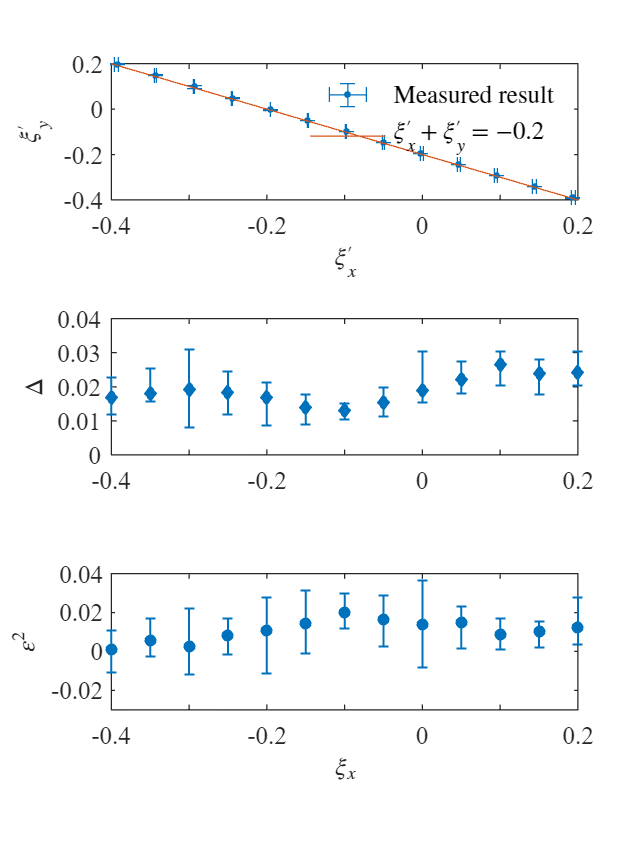

% load Epsilon_N=8_ave100.mat  
% y3=Epsilon(:,:,3).^2; %Epsilon(:,:,1)--for tau=1 us, Epsilon(:,:,2)--for tau=3 us, Epsilon(:,:,3)--for tau=5 us
% 
% [vari,mean_y]=var(y3,[],2);
% max_y=max(y3,[],2);
% min_y=min(y3,[],2);
% errorbar_neg=mean_y-min_y;
% errorbar_pos=max_y-mean_y;
% 
% % [vari,mean_y]=var(y3,[],2);
% % errorbar_neg=vari.^0.5;
% % errorbar_pos=vari.^0.5;
% 
% errorbar(xi_x_ideal,mean_y,errorbar_neg,errorbar_pos,'s','LineWidth',0.8,'markersize',4,'capsize',4,'MarkerFaceColor',color{2})
% 
xticks([-0.4:0.1:0.2])
xticklabels({'-0.4','','-0.2','','0','','0.2'})
ylim([-0.03 0.04])
% 
% legend('Exp','Nume','box','off')

fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,9,12]);
fontsize(gcf,10,'points')